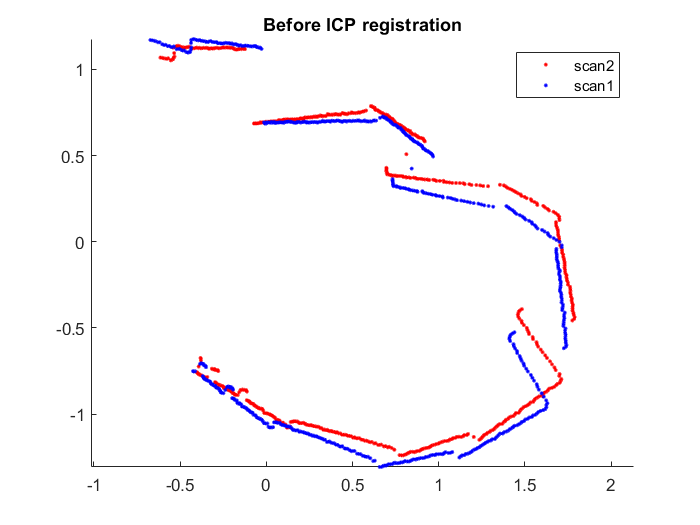

% parameters
dim = 2;
iters= 500;
% R_init and T_init are the initial guess parameters
R_init = eye(2); 
T_init = zeros(2,1); 
% Maximum distance treshold to eliminate the outlier correspondances. This has to 
% be tuned. 
max_tresh = 10 ; 
% loading raw scans
lidar_scans = load('lidar_scans.mat');
scan1 = lidar_scans.scan1;
scan2 = lidar_scans.scan2;
% Remove zero columns in the scans (if any)
scan1( :, ~any(scan1,1) ) = [];
scan2( :, ~any(scan2,1) ) = [];
%% Perform  ICP 
[R,T] =  icpAlgorithm(scan1,scan2,iters,R_init,T_init,max_tresh); % ---------------> TO DO
 
% Note: find R,T such that they register scan2 onto scan1. This is just to maintain
%       uniformity.  
 
%% Visualizing the output
scan2_transformed = R*scan2+repmat(T,1,size(scan2,2));
figure 
scatter(scan2(1,:),scan2(2,:),'r','.');
hold on
scatter(scan1(1,:),scan1(2,:),'b','.');
axis equal
title('Before ICP registration')
legend('scan2','scan1');

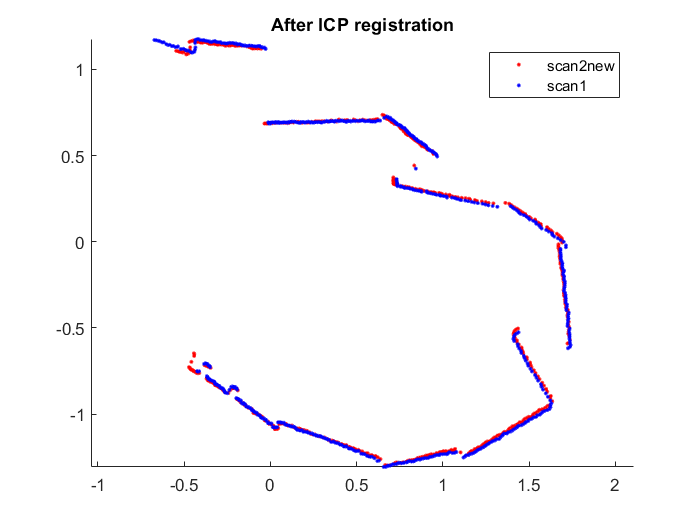

 
figure
scatter(scan2_transformed(1,:),scan2_transformed(2,:),'r','.');
hold on
scatter(scan1(1,:),scan1(2,:),'b','.');
axis equal
title('After ICP registration')
legend('scan2new','scan1');

function [R_matrix,T_matrix] = icpAlgorithm(scan1, scan2, iterations, R_initial, T_initial, threshold)
    
    % Initializing the parameters 
    align_error_thresh = 6.2e-04;
    R_matrix = R_initial;
    T_matrix = T_initial;
    
    for i=1:iterations
        % Transforming the scan2 in the frame of reference of scan1
        scan2_transformed = R_matrix*scan2 + repmat(T_matrix,1,length(scan2));
        
        % Updating scan2 according to the correspondances
        scan2_transformed = calculateCorrespondance(scan1, scan2_transformed, threshold);
        
        % Computing the rotation and translation matrices using the SVD
        % algorithm
        mean1 = mean(scan1, 2);
        mean2 = mean(scan2_transformed, 2);
        
        % X = X - mean(X)
        A = scan1 - repmat(mean1,1,length(scan1));
        B = scan2_transformed - repmat(mean2,1,length(scan2_transformed));
        
        % C = covariance matrix of scan1 and scan2_transformed
        C = A*transpose(B);
        [U,~,V] = svd(C);
        
        % Updating the rotation and the translation matrices
        R_matrix = U*transpose(V)*R_matrix;
        T_matrix = mean1 - (U*transpose(V))*mean2 + T_matrix;
        
        % Computing the alignment error between the two scans
        % e = sqrt((x1-x2)^2 + (y1-y2)^2)
        align_error = sqrt(sum((scan1(1,:)-scan2_transformed(1,:)).^2 +...
                        (scan1(2,:)-scan2_transformed(2,:)).^2))/length(scan1);
        if(align_error<align_error_thresh)
            break;
        end
        
    end
end

function [filtered_scan] = calculateCorrespondance(scan1, scan2, threshold)
    
    % Initialing the output array
    filtered_scan = zeros(size(scan2));
    
    % Finding the correspondance points
    for i=1:length(scan1)
        emin = inf;
        for j=1:length(scan2)
            e = norm(scan1(:,i) - scan2(:,j));
            if (e<emin) && (e<threshold)
                % if the above conditions hold true,
                % then there is a correspondance between
                % the ith point in scan1 and jth point
                % in scan2. 
                emin = e;
                filtered_scan(:,i) = scan2(:,j);
            end
        end
    end
    
end
